This live script describes the table mAllData that is saved as a variable in mAllData_VR.mat

The table has 28 columns (variables), and is summarizing the results from two-photon experiment of a fly on a ball.

Each line in the table is a single stimulus. Tens of stimuli are presented to each fly, and the StimNumber variable is the stimulus number that was presented to the fly.

Table variables:

**StimName** is the name of the stimulus, as apears in the CTRL file.

For example: 16PDUR_20PPAU_16PNUM_250CAR means: a train of 16 Drosophila song pulses, each pulse in 16ms wide, 20ms pause between pulses (so inter-pulse-interval = 36ms), with carrier frequency of 250ms.

**Folder** is the name of the folder. One Folder = One Fly.        **Gender**  - F/M for Female/Male

**StimNumber** - serial number of the stimuli presented to a given fly

**FramesPerSecond** - in the two-photon imaging system

**SamplesPerSecond** - in the NI-DAQ that controls the stimulus (typically 10000 samples per second)

**FrameStartStim** is the number if frame in the TIFF file - the output of the two-photon imaging acquisition system.

For example,  if the stimulus (e.g., the pulse song train) starts 5 second after the trial start (so 5 seconds pre-stimulus) and we image at 55.249Hz, than FrameStartStim will be round(5*55.249)=276.

**ROIname** - the ROI was defined manually by the user who also gave it a name (e.g., 'Ring', 'pC2Cell')

**ROISide** - left/Right hemisphere

**GreenSignal_FinROI** - Flourescence in ROI of green PMT (GCaMP response)

**GreenSignal_DFFinROI** - DF/F in ROI of green PMT (GCaMP response)

**RedSignal** - TdTomato channel (can be used as a reference or for motion correction)

**GreenSignal_MaxDFF** - max(GreenSignal_DFFinROI )

**GreenSignal_SumDFF** - sum(GreenSignal_DFFinROI)

**MaxDFFAllStim **- For a give fly (!) what was max over all GreenSignal_MaxDFF. Used for normalization.

**MaxSumDFFAllStim** - For a give fly (!) what was max over all GreenSignal_SumDFF. Used for normalization.

**Intensity** - of the stimulus in mm/sec (given that the system iscalibrated)

**Housed** - S/G - flies where single or group housed since they were born until they were imaged.

**Stim** - The trace of the stimulus for the given trial (X axis in SamplePerSecond).

**STIMON_sample** - When the stimulus=~0 for the firt time in the trial.

**STIMOFF_sample **- When the stimulus ~=0 for the last time in the trial

**STIMON_ImFrame** - The frame in the TIFF file (imaging output file) when the stimulus was ON

**STIMOFF_ImFrame** - The frame in the TIFF file (imaging output file) when the stimulus was OFF

**StartTrial_FicTracFrame **- The is a single tracking (.avi) movie for one fly. This is the frame when the trial starts. 

**EndTrial_FicTracFrame** - ...and this is the frame in the movie 

**STIMON_FicTracFrame** - The frame 

**STIMOFF_FicTracFrame** - 

- All the FicTracFrames corresponds to the frame number in the first column of FicTracSpeed (see the line below)

**FicTracSpeed** - Thie first 4 columns from the .dat file - the output of FicTrac, but only for the frames in the range

StartTrial_FicTracFrame:EndTrial_FicTracFrame

- Columns 1-4 are: Frame number, X-speed, Y-speed and Z-speed

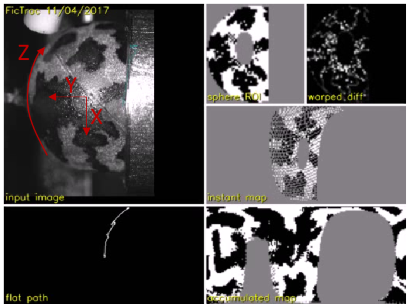

%first load the mat file that contains the table
%Note - fix the filename depending on where the file is saved!! - 
filename = 'Z:\Dudi\Imaging\2Photon\Dudi_setup\DSX_VR2P_Auditory\mAllData_VR.mat';
load(filename)

Below is a short code for showing the stimulus/calcium response/ball motion trial by trial

figure
for nLine = 1:size(mAllData,1)
    %Stimulus
    subplot(311),hold off
    plot(mAllData.Stim{nLine}),axis tight
    title('Stimulus')
    %FinROI (green channel)
    subplot(312),hold off
    SmoothFinROI =  movmedian(mAllData.GreenSignal_FinROI{nLine},7);
    DeltaFinROI = SmoothFinROI - mean(SmoothFinROI(1:200));
    %DeltaFinROI = mAllData.GreenSignal_FinROI{nLine} - mean(mAllData.GreenSignal_FinROI{nLine}(1:200));
    plot(DeltaFinROI),axis tight
    title('F in ROI')
    %SpeedOnBall
    subplot(313),hold off
    X = mAllData.FicTracSpeed{nLine}(:,1)-mAllData.FicTracSpeed{nLine}(1,1)+1;
    Y = abs(mAllData.FicTracSpeed{nLine}(:,2));% columns 2/3/4 for X/Y/Z axis of fly rotation 
    plot(X,Y), axis tight
    ylim([-0.2 0.2])
    title('Speed')
    pause
end

and here is an example for a short code for looking at the correlation between fly calcium response and fly absolute speed in Z (side walk) after stimulus on in a given window

- Can probably do a better job by normalizing the calcium response to the max response per fly

- This is a very naive approach  - just an example for using the data.

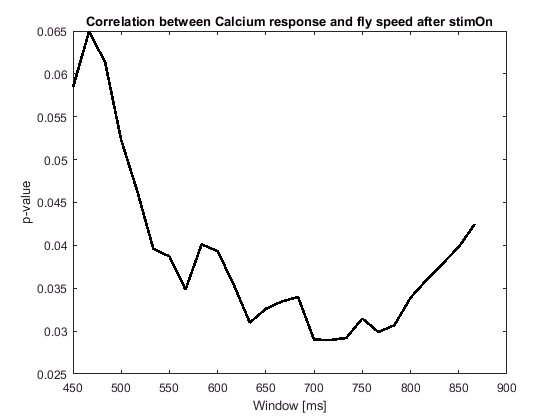

vWindow = 27:52;%frames in the tracking movie/FicTrac output. For example 42 frames are 
%42*(1000/60) = 700ms window

PP = zeros(1,length(vWindow));%p-values
RR = zeros(1,length(vWindow));%correlations

for ii = 1:length(vWindow)%looking at the correlation for different windows
 
Safter = zeros(1,size(mAllData,1)); CaResponse = zeros(1,size(mAllData,1));%memory allocation
for nLine = 1:size(mAllData,1)  
    Y = abs(mAllData.FicTracSpeed{nLine}(:,4));%Z-axis
    StartStimInCurrenTrial_FicTrac = ...
        mAllData.STIMON_FicTracFrame{1} - mAllData.StartTrial_FicTracFrame{1};
    Safter(nLine) = mean(Y(StartStimInCurrenTrial_FicTrac:StartStimInCurrenTrial_FicTrac+vWindow(ii)));
    %Safter = Speed after stim on
    
    SmoothFinROI =  movmean(mAllData.GreenSignal_FinROI{nLine},7);%smoothing with a moving window
    DeltaFinROI = SmoothFinROI - mean(SmoothFinROI(1:200));%take frames before StimOn for baseline
    CaResponse(nLine) = max(DeltaFinROI);
end
[R, P] = corrcoef(Safter,M);%the correlation and p-value berween Calcium response and fly speed
PP(ii) = P(1,2);
RR(ii) = R(1,2);

end

figure,subplot(111),hold off
plot(vWindow*1000/60,PP,'k','LineWidth',2)%1000/60 to convert to milliseconds
title('Correlation between Calcium response and fly speed after stimOn')
xlabel('Window [ms]'), ylabel('p-value')